# MATLAB Exercise 6.9:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Design Butterworth, Chebyshev type-I, Chebyshev type-II and elliptic analog bandpass filters to meet the specifications below:

 
$$\left.\begin{array}{r c l}
-3\le\left|H\left(f\right)\right|_{dB}\le 0 & \textrm{for} & 2\le f\le 3\;\textrm{Hz} \\
\left|H\left(f\right)\right|_{dB}\le -25.0 & \textrm{for} & f \le 1.5\;\textrm{Hz}\;\;\textrm{or}\;\;f\ge 3.5\;\textrm{Hz}
\end{array}$$


% Enter specifications
Rp = 3;
As = 25;
fp = [2,3];         % Passband edge frequencies in Hz
fs = [1.5,3.5];     % Stopband edge frequencies in Hz
Wp = 2*pi*fp;       % Passband edge frequencies in rad/s
Ws = 2*pi*fs;       % Stopband edge frequencies in rad/s
f = [0:0.005:7];    % Vector of frequencies for graphing
omg = 2*pi*f;

% Butterworth filter
[N,Wn] = buttord(Wp,Ws,Rp,As,'s');   % Compute Butterworth parameters
[num1,den1] = butter(N,Wn,'s');      % Design Butterworth filter
disp('Butterworth filter:');

Butterworth filter:


H1 = tf(num1,den1)

H1 =
 
                                                                 1.001e04 s^5
  -------------------------------------------------------------------------------------------------------------------------------------------
  s^10 + 20.42 s^9 + 1393 s^8 + 2.067e04 s^7 + 7.144e05 s^6 + 7.509e06 s^5 + 1.692e08 s^4 + 1.16e09 s^3 + 1.851e10 s^2 + 6.43e10 s + 7.457e11
 
Continuous-time transfer function.


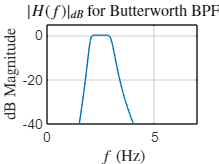

H1dB = dBMagnitude(num1,den1,omg);
plot(f,H1dB); grid;
axis([0,7,-40,5]);
set(0,'defaultTextInterpreter','latex');
xlabel('$f$ (Hz)');
ylabel('dB Magnitude');
title('$|H(f)|_{dB}$ for Butterworth BPF')

% Chebyshev type-I filter
[N,Wp] = cheb1ord(Wp,Ws,Rp,As,'s');  % Compute Chebyshev type-I parameters
[num2,den2] = cheby1(N,Rp,Wp,'s');   % Design Chebyshev type-I filter
disp('Chebyshev type-I filter:');

Chebyshev type-I filter:


H2 = tf(num2,den2)

H2 =
 
                                                   195.3 s^4
  -----------------------------------------------------------------------------------------------------------
  s^8 + 3.654 s^7 + 993.6 s^6 + 2697 s^5 + 3.588e05 s^4 + 6.389e05 s^3 + 5.575e07 s^2 + 4.856e07 s + 3.148e09
 
Continuous-time transfer function.
Model Properties


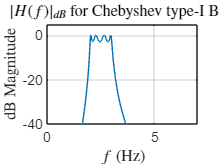

H2dB = dBMagnitude(num2,den2,omg);
plot(f,H2dB); grid;
axis([0,7,-40,5]);
xlabel('$f$ (Hz)');
ylabel('dB Magnitude');
title('$|H(f)|_{dB}$ for Chebyshev type-I BPF')

% Chebyshev type-II filter
[N,Ws] = cheb2ord(Wp,Ws,Rp,As,'s');  % Compute Chebyshev type-II parameters
[num3,den3] = cheby2(N,As,Ws,'s');   % Design Chebyshev type-II filter
disp('Chebyshev type-II filter:');

Chebyshev type-II filter:


H3 = tf(num3,den3)

H3 =
 
  0.05623 s^8 + 4.757e-16 s^7 + 89.38 s^6 + 4.453e-13 s^5 + 3.893e04 s^4 + 6.46e-11 s^3 + 5.015e06 s^2 + 3.159e-09 s + 1.77e08
  ----------------------------------------------------------------------------------------------------------------------------
         s^8 + 17.96 s^7 + 1111 s^6 + 1.362e04 s^5 + 4.169e05 s^4 + 3.227e06 s^3 + 6.233e07 s^2 + 2.387e08 s + 3.148e09
 
Continuous-time transfer function.


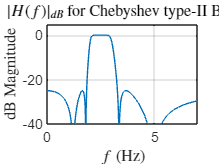

H3dB = dBMagnitude(num3,den3,omg);
plot(f,H3dB); grid;
axis([0,7,-40,5]);
xlabel('$f$ (Hz)');
ylabel('dB Magnitude');
title('$|H(f)|_{dB}$ for Chebyshev type-II BPF')

% Elliptic filter
[N,Wp] = ellipord(Wp,Ws,Rp,As,'s');  % Compute elliptic filter parameters
[num4,den4] = ellip(N,Rp,As,Wp,'s'); % Design elliptic filter
disp('Elliptic filter:');

Elliptic filter:


H4 = tf(num4,den4)

H4 =
 
  1.093 s^5 - 2.938e-15 s^4 + 603.5 s^3 - 1.119e-12 s^2 + 6.133e04 s + 2.44e-12
  -----------------------------------------------------------------------------
  s^6 + 3.685 s^5 + 749.5 s^4 + 1831 s^3 + 1.775e05 s^2 + 2.068e05 s + 1.329e07
 
Continuous-time transfer function.
Model Properties


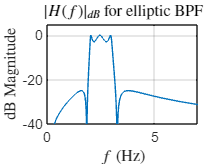

H4dB = dBMagnitude(num4,den4,omg);
plot(f,H4dB); grid;
axis([0,7,-40,5]);
xlabel('$f$ (Hz)');
ylabel('dB Magnitude');
title('$|H(f)|_{dB}$ for elliptic BPF')

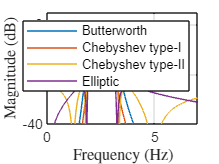

% Graph all results
p = plot(f,H1dB,f,H2dB,f,H3dB,f,H4dB); grid;
axis([0,7,-40,5]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('Butterworth','Chebyshev type-I','Chebyshev type-II','Elliptic',...
    'Location','NorthEast');

set(0,'defaultTextInterpreter','tex');

function HdB = dBMagnitude(num,den,omg)
  % Function to compute dB magnitude from numerator and denominator
  H = freqs(num,den,omg);
  HdB = 20*log10(abs(H));
end